# Honours Live Script 4

## Load and Save Data

if ~exist("workspaceVarHonours", 'var')
    load matlabHonours.mat
    setInterpLatex()
end

if exist("workspaceVarHonours", 'var')
    clearVarsArray = clearVars();
    clear(clearVarsArray{:})
    clear clearVarsArray
    save matlabHonours.mat
end 

% set the default intepreter to latex
setInterpLatex()

## Contents

Extracting GBR Subset

MPA Impact Parameter Setting

Coral Trout Simulations

Analysing Results - South GBR

## Assumptions Made

% note that specStructCT is set in the previous live script, and contains
% the parameters from Bode et al. 2012 surrogates

% I've retroactively added the masses to the species struct here lol
specStructCT.weightings = massVecCT;

## Extracting GBR Subset

% need to extract the subset of reefs which we are going to use for this
% experiment

% first, I'm testing out my code now that areas are a part of it
var1 = ones(10, 11, 12);
var2 = 0.01 * ones(10, 1);
var2(2:2:end) = 1;
var3 = var1 .* var2
var1 = baseMetapopModel(rand(10), var2, rand(10, 14), 10, specStructCT);
figure
imagesc(var1(:, :, 10))
colormap(myColourMap())
colorbar
darkFig()

% now, I'll figure out the tolerance which I can use to extract the reefs I
% want
southReefsCT = centroidsCT(:, 2) < -22.5;
nReefsCTSouth = sum(southReefsCT);

% those look good, so let's grab out the connectivity matrices and other
% things that I need
conMatsCTSouth = conMatsCT;
for m = 1:nMatsCT
    conMatsCTSouth{m} = conMatsCT{m}(southReefsCT, southReefsCT);
end
areasCTSouth = areasCT(southReefsCT);
GBRShapeCTSouth = GBRShapeCT(southReefsCT);
centroidsCTSouth = centroidsCT(southReefsCT, :);

% visualise the selection
figure
hold on
plot(centroidsCT(southReefsCT, 1), centroidsCT(southReefsCT, 2), '.', 'Color', ...
    getColour('g'))
plot(centroidsCT(~southReefsCT, 1), centroidsCT(~southReefsCT, 2), 'k.')
axis equal
darkFig()

figure
hold on
plotShapeStruct(GBRShapeCTSouth)
plot(centroidsCTSouth(:, 1), centroidsCTSouth(:, 2), 'k.')
darkFig()

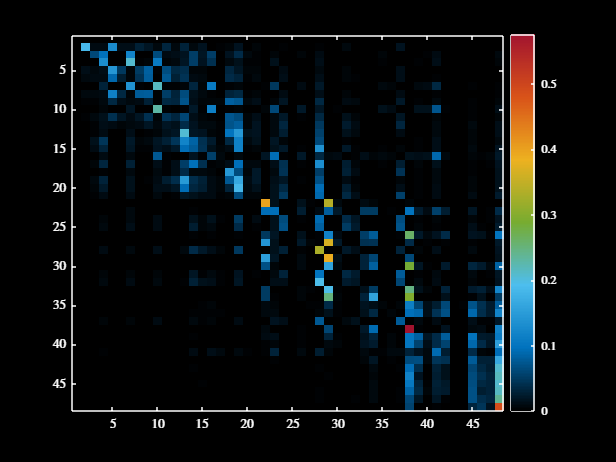

% out of interest, let's plot a couple
m = 23;
figure
imagesc(conMatsCTSouth{m})
colormap(myColourMap())
colorbar
darkFig()

figure
plot(sort(areasCTSouth))
darkFig()

## MPA Impact Parameter Setting

% run the simulation for a long enough period of time so that the
% populations will stabilise
tWarmup = 1000;
randStruct.randType = "sequence";
randStruct.sequence = randi(length(conMatsCT), 1, tWarmup - 1);
popInitTest = repmat(areasCTSouth, [1, 14]);
popMatTest = baseMetapopModel(conMatsCTSouth, areasCTSouth, ...
        popInitTest, tWarmup, specStructCT, randStruct);

% check the number of reefs which have gone extinct
test = sum(popMatTest(:, :, end), 2);
sum(test == 0)

% I'm just going to set the initial populations for each reef in the
% simulations below as the mean of the last 100 years
popInitCTSouth = mean(popMatTest(:, :, (end - 100):end), 3);

% visualise a random selection of the reefs
var1 = [1, 4, 5, 7, 30, 40];
tL = visualiseMetapop(popMatTest(var1, :, :), 1:tWarmup);
title(tL, "Coral Trout Test Run", 'Interpreter', 'Latex')
darkFig(tL)
figResize(1.75)
% saveCoolFig("CoralTroutRun2", "labelsLegend")

% plot the distribution of the total populations for the reefs
figure
plot(sort(test))
darkFig()

t = 200
figure
imagesc(popMatTest(:, :, t))
colormap(myColourMap())
colorbar
darkFig()
mean(popMatTest(:, :, t), "all")
sum(popMatTest(:, :, t), "all")

% want to do an updated version of the MPA succession probabilities which
% better align with the unpublished work by Mike
rng(1)
var1 = [1, 4, 5, 7, 30, 40];
tMax = 50;
successVecCTMPA = cat(2, [0.6, 0.7, 0.83], repmat(0.94, [1, 10]));
actionStruct.type = "MPA";
actionVec = zeros(1, nReefsCTSouth);
actionVec(var1) = 1;
actionStruct.actionVec = actionVec;
actionStruct.actionEffect = successVecCTMPA;
popInitTest = 50 * ones(nReefsCTSouth, 14);
actionStruct.type = "MPA";

% run without the MPA
popMatTest1 = baseMetapopModel(conMatsCTSouth, areasCTSouth, ...
        popInitCTSouth, tMax, specStructCT, randStruct);

% run with the MPA
popMatTest2 = baseMetapopModel(conMatsCTSouth, areasCTSouth, ...
        popInitCTSouth, tMax, specStructCT, randStruct, actionStruct);

% convert the results to biomasses
biomassMat1 = convertAgeClasses(popMatTest1, massVecCT);
biomassMat2 = convertAgeClasses(popMatTest2, massVecCT);

% plot the results
figure
hold on
for r = 1:length(var1)
    plot(biomassMat1(var1(r), :), 'Color', getColour(r))
    plot(biomassMat2(var1(r), :), '--', 'Color', getColour(r))
end
xlabel("Time (years)")
ylabel("Total Biomass")
title("Effect of MPA")
subtitle("Solid = without MPA, Dashed = MPA")
legend()
darkFig()

## Coral Trout Simulations

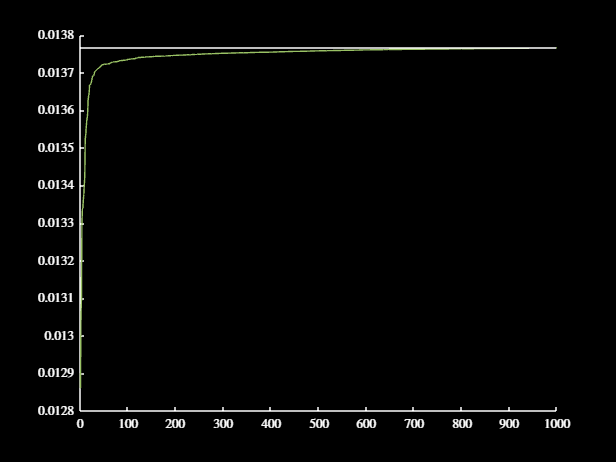

% set up the random portfolio loop here and make sure I'm doing it
% correctly
resourcesCTSouth = 0.3 * sum(areasCTSouth);

% add reefs sequentially, if their addition won't exceed the total
% resources available
var1 = zeros(1000, 1);
for i = 1:1000
    reefSeq = randperm(nReefsCTSouth);
    randPort = zeros(1, nReefsCTSouth);
    for r = 1:nReefsCTSouth
        randPortTemp = randPort;
        randPortTemp(reefSeq(r)) = 1;
        if randPortTemp * areasCTSouth < resourcesCTSouth
            randPort = randPortTemp;
        end
    end
    var1(i) = randPort * areasCTSouth;
    if var1(i) > resourcesCTSouth
        disp(i)
    end
end

% plot the results
figure
hold on
plot(sort(var1), 'Color', getColour('g'))
yline(resourcesCTSouth)
darkFig()

% run the simulations :)
nRepsCT = 100;
tWarmup = 100;
tObs = 20;
tFinal = 50;
randStruct = struct();
randStruct.randType = "sequence";
actionStruct.type = "MPA";
actionStruct.actionEffect = successVecCTMPA;
portPerfCTSouth = zeros(nRepsCT, 7);
portPerfCTSouthRetro = zeros(nRepsCT, 7);

% because I'm a genius, I'm gonna store the MPAs created at each rep AND
% the random connectivity matrix sequences at each rep - that way I can
% reliably recreate the population trajectories without re - running
% everything
mpaSelCTSouth = cell(nRepsCT, 1);
randSeqCTSouth = cell(nRepsCT, 3);

% also, the costs will be the areas, and the resources will be 30% of the
% entire area
resourcesCTSouth = 0.3 * sum(areasCTSouth);

% time stuff
tic

% loop over each run
for r = 1:nRepsCT

    % run the metapopulation model for the warmup period
    randStruct.sequence = randi(nMatsCT, 1, tWarmup - 1);
    randSeqCTSouth{r, 1} = randStruct.sequence;
    popMatWarmup = baseMetapopModel(conMatsCTSouth, areasCTSouth, ...
        popInitCTSouth, tWarmup, specStructCT, randStruct);

    % run the metapopulation model for the observational period
    randStruct.sequence = randi(nMatsCT, 1, tObs - 1);
    randSeqCTSouth{r, 2} = randStruct.sequence;
    popMatObs = baseMetapopModel(conMatsCTSouth, areasCTSouth, ...
        squeeze(popMatWarmup(:, :, end)), tObs, specStructCT, ...
        randStruct);

    % convert the age structured population trajectories into a single,
    % size class weighted sum
    biomassMat = convertAgeClasses(popMatObs, massVecCT);

    % run the decision making code to choose the MPAs for each of the
    % options, first calculating the weight = 1 and weight = 0 portfolios,
    % as these will contributed to the boundVals inputs for the following
    % runs
    boundVals = zeros(2, 2);
    mpaSelCTSouth{r} = cell(1, 7);
    [mpaSelCTSouth{r}{1}, boundVals(1, 2), boundVals(2, 2)] = applyMPT( ...
        biomassMat, 1, "discrete", resourcesCTSouth, areasCTSouth);
    [mpaSelCTSouth{r}{5}, boundVals(1, 1), boundVals(2, 1)] = applyMPT( ...
        biomassMat, 0, "discrete", resourcesCTSouth, areasCTSouth);
    mpaSelCTSouth{r}{2} = applyMPT(biomassMat, 0.75, "discrete", ...
        resourcesCTSouth, areasCTSouth, boundVals);
    mpaSelCTSouth{r}{3} = applyMPT(biomassMat, 0.5, "discrete", ...
        resourcesCTSouth, areasCTSouth, boundVals);
    mpaSelCTSouth{r}{4} = applyMPT(biomassMat, 0.25, "discrete", ...
        resourcesCTSouth, areasCTSouth, boundVals);

    % form the random portfolio, and the zero portfolio
    reefSeq = randperm(nReefsCTSouth);
    mpaSelCTSouth{r}{6} = zeros(1, nReefsCTSouth);
    for i = 1:nReefsCTSouth
        randPortTemp = mpaSelCTSouth{r}{6};
        randPortTemp(reefSeq(i)) = 1;
        if randPortTemp * areasCTSouth < resourcesCTSouth
            mpaSelCTSouth{r}{6} = randPortTemp;
        end
    end
    mpaSelCTSouth{r}{7} = zeros(1, nReefsCTSouth);

    % test the retroactive performance of the MPAs
    popMatCell = cell(1, length(mpaSelCTSouth{r}));
    for m = 1:length(mpaSelCTSouth{r})
        actionStruct.actionVec = mpaSelCTSouth{r}{m};
        popMatCell{m} = baseMetapopModel(conMatsCTSouth, areasCTSouth, ...
            squeeze(popMatWarmup(:, :, end)), tObs, specStructCT, ...
            randStruct, actionStruct);
    end

    % evaluate the retroactive performance of the MPA selections
    for m = 1:length(mpaSelCTSouth{r})
        portPerfCTSouthRetro(r, m) = objFuncMPA(popMatCell{m}, massVecCT);
    end

    % select a sequence of connectivity matrices for the final time period,
    % which will be the same across all portfolio samples
    randStruct.sequence = randi(nMatsCT, 1, tFinal - 1);
    randSeqCTSouth{r, 3} = randStruct.sequence;

    % run each of the models for the rest of the testing period
    popMatCell = cell(1, length(mpaSelCTSouth{r}));
    for m = 1:length(mpaSelCTSouth{r})
        actionStruct.actionVec = mpaSelCTSouth{r}{m};
        popMatCell{m} = baseMetapopModel(conMatsCTSouth, areasCTSouth, ...
            squeeze(popMatObs(:, :, end)), tFinal, specStructCT, ...
            randStruct, actionStruct);
    end

    % evaluate the performance of each of the MPA selections
    for m = 1:length(mpaSelCTSouth{r})
        portPerfCTSouth(r, m) = objFuncMPA(popMatCell{m}, massVecCT);
    end

    % every 10 iterations print the time
    if mod(r, 10) == 0
        disp(r)
        toc
        currTime = toc;
    end

end

% clear some of the redundant variables
clear popMatCell popMatWarmup popMatObs

% load in the data from the code I ran from my PC
load matlabCTSouthExp.mat

% re - run the simulations under the same conditions, but this time
% evaluate the variance of the year - to - year size weighted sum of
% performance - just make sure that the nRepsCT, and times are all
% consistent
nRepsCT = 100;
tWarmup = 100;
tObs = 20;
tFinal = 50;
portVarCTSouthRetro = zeros(size(portPerfCTSouthRetro));
portVarCTSouth = zeros(size(portPerfCTSouth));

% loop over each run
for r = 1:nRepsCT

    % run the metapopulation model for the warmup period
    randStruct.sequence = randSeqCTSouth{r, 1};
    popMatWarmup = baseMetapopModel(conMatsCTSouth, areasCTSouth, ...
        popInitCTSouth, tWarmup, specStructCT, randStruct);

    % run the metapopulation model for the observational period
    randStruct.sequence = randSeqCTSouth{r, 2};
    popMatObs = baseMetapopModel(conMatsCTSouth, areasCTSouth, ...
        squeeze(popMatWarmup(:, :, end)), tObs, specStructCT, ...
        randStruct);

    % test the retroactive performance of the MPAs
    popMatCell = cell(1, length(mpaSelCTSouth{r}));
    for m = 1:length(mpaSelCTSouth{r})
        actionStruct.actionVec = mpaSelCTSouth{r}{m};
        popMatCell{m} = baseMetapopModel(conMatsCTSouth, areasCTSouth, ...
            squeeze(popMatWarmup(:, :, end)), tObs, specStructCT, ...
            randStruct, actionStruct);
    end

    % evaluate the variance in the retroactive performance of the MPA
    % selections
    for m = 1:length(mpaSelCTSouth{r})
        [~, perfTimed] = objFuncMPA(popMatCell{m}, massVecCT);
        portVarCTSouthRetro(r, m) = var(perfTimed);
    end

    % select a sequence of connectivity matrices for the final time period,
    % which will be the same across all portfolio samples
    randStruct.sequence = randSeqCTSouth{r, 3};
    randSeqCTSouth{r, 3} = randStruct.sequence;

    % run each of the models for the rest of the testing period
    popMatCell = cell(1, length(mpaSelCTSouth{r}));
    for m = 1:length(mpaSelCTSouth{r})
        actionStruct.actionVec = mpaSelCTSouth{r}{m};
        popMatCell{m} = baseMetapopModel(conMatsCTSouth, areasCTSouth, ...
            squeeze(popMatObs(:, :, end)), tFinal, specStructCT, ...
            randStruct, actionStruct);
    end

    % evaluate the variance performance of each of the MPA selections
    for m = 1:length(mpaSelCTSouth{r})
        [~, perfTimed] = objFuncMPA(popMatCell{m}, massVecCT);
        portVarCTSouth(r, m) = var(perfTimed);
    end

end

% clear some redundant variables
clear popMatCell popMatWarmup

## Analysing Results - South GBR

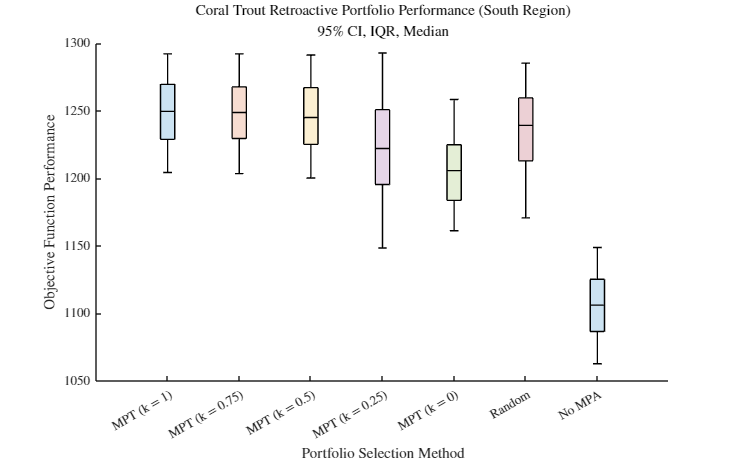

% now, plot the results for the retroactive and future approaches
names = ["MPT (k = 1)", "MPT (k = 0.75)", "MPT (k = 0.5)", ...
    "MPT (k = 0.25)", "MPT (k = 0)", "Random", "No MPA"];
figure
myBoxPlot(portPerfCTSouthRetro, names)
xlabel("Portfolio Selection Method")
ylabel("Objective Function Performance")
title("Coral Trout Retroactive Portfolio Performance (South Region)")
figRect(1, 1.2)
saveFig("CT Portfolio Performance Retroactive (South Region)")

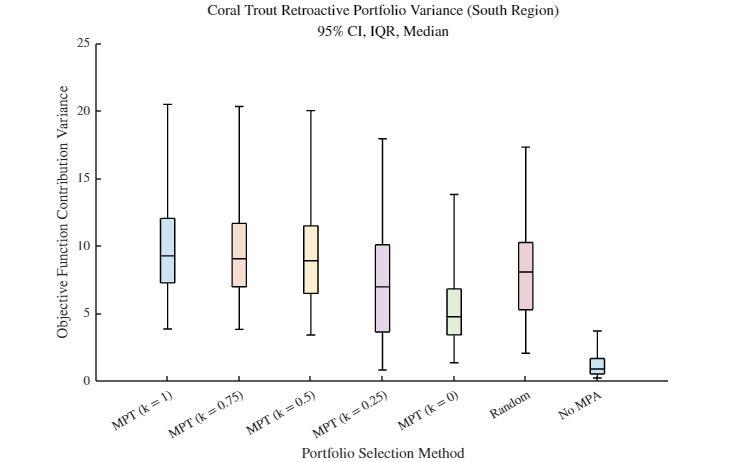

% darkFig()

% look at the variance in yearly objective function contribution
figure
myBoxPlot(portVarCTSouthRetro, names)
xlabel("Portfolio Selection Method")
ylabel("Objective Function Contribution Variance")
title("Coral Trout Retroactive Portfolio Variance (South Region)")
figRect(1, 1.2)
saveFig("CT Portfolio Variance Retroactive (South Region)")

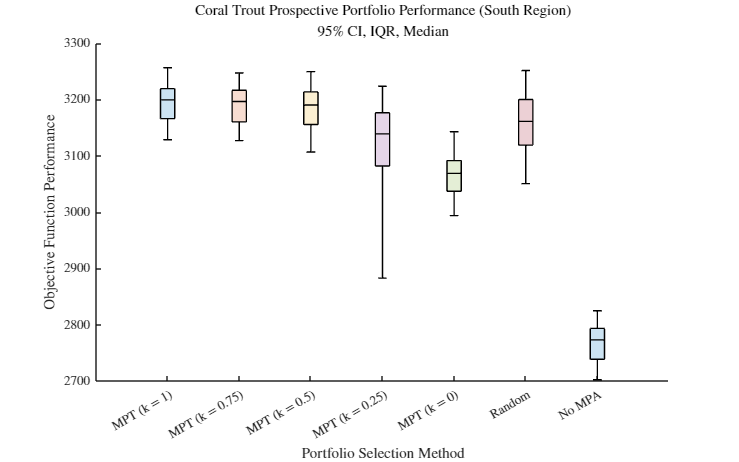


% plot the prospective performance
figure
myBoxPlot(portPerfCTSouth, names)
xlabel("Portfolio Selection Method")
ylabel("Objective Function Performance")
title("Coral Trout Prospective Portfolio Performance (South Region)")
figRect(1, 1.2)
saveFig("CT Portfolio Performance Prospective (South Region)")

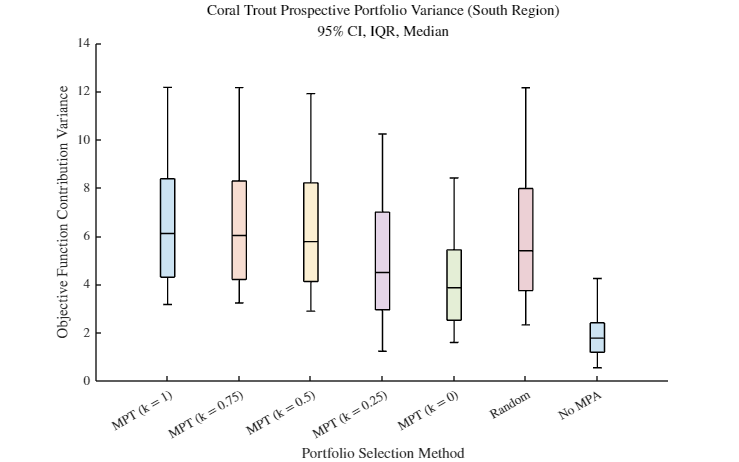


% plot the prospective portfolio variance
figure
myBoxPlot(portVarCTSouth, names)
xlabel("Portfolio Selection Method")
ylabel("Objective Function Contribution Variance")
title("Coral Trout Prospective Portfolio Variance (South Region)")
figRect(1, 1.2)
saveFig("CT Portfolio Variance Prospective (South Region)")

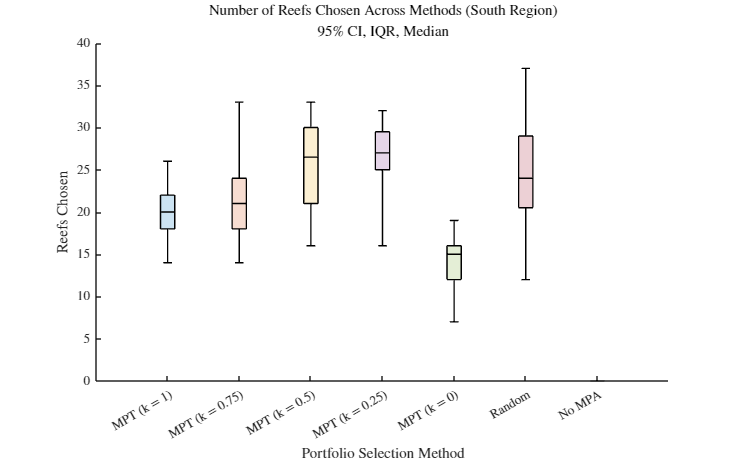


% make a boxplot of the number of reefs chosen
numReefsChosen = zeros(size(portPerfCTSouthRetro));
for m = 1:size(portPerfCTSouthRetro, 2)
    for r = 1:size(portPerfCTSouthRetro, 1)
        numReefsChosen(r, m) = sum(mpaSelCTSouth{r}{m});
    end
end
figure
myBoxPlot(numReefsChosen, names)
xlabel("Portfolio Selection Method")
ylabel("Reefs Chosen")
title("Number of Reefs Chosen Across Methods (South Region)")
figRect(1, 1.2)
saveFig("CT Number Reefs Chosen (South Region)")

% darkFig()

% maybe I'm paranoid, but should make sure the portfolios formed are valid
% here (when I can be bothered)

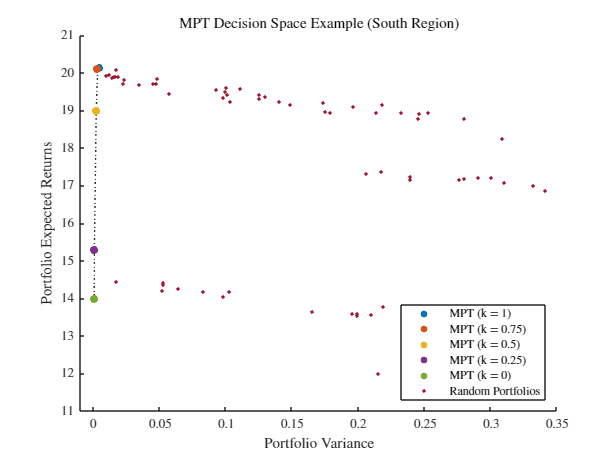

% make the fun little plot of the portfolios for a single example
r = 1;
[portPerfMPT, portPerfRand] = mptVisSimulation(conMatsCTSouth, ...
    areasCTSouth, popInitCTSouth, resourcesCTSouth, randSeqCTSouth, mpaSelCTSouth, ...
    specStructCT, actionStruct.actionEffect, r);

% plot the performance of the selected reefs only, before the MPAs are
% simulated
figure
visualiseMPT(portPerfMPT{1, 1}, portPerfMPT{1, 2}, names, portPerfRand{1, 1}, ...
    portPerfRand{1, 2}, "rand")
title("MPT Decision Space Example (South Region)")
xlim([-0.01, 0.35])
hLegend = findobj(gcf, 'Type', 'Legend');
hLegend.Location = 'southeast';
saveFig("MPT Decision Space Example (South Region)")

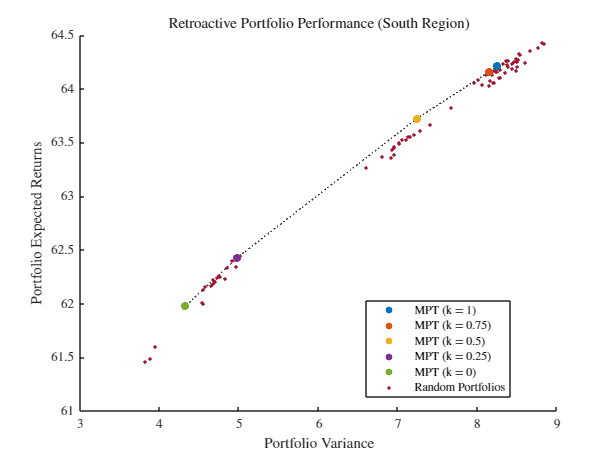


% plot the results for the actual performances on historical connectivity
% matrices
figure
visualiseMPT(portPerfMPT{2, 1}, portPerfMPT{2, 2}, names, portPerfRand{2, 1}, ...
    portPerfRand{2, 2}, "rand")
title("Retroactive Portfolio Performance (South Region)")
saveFig("Retroactive Portfolio Performance (South Region)")

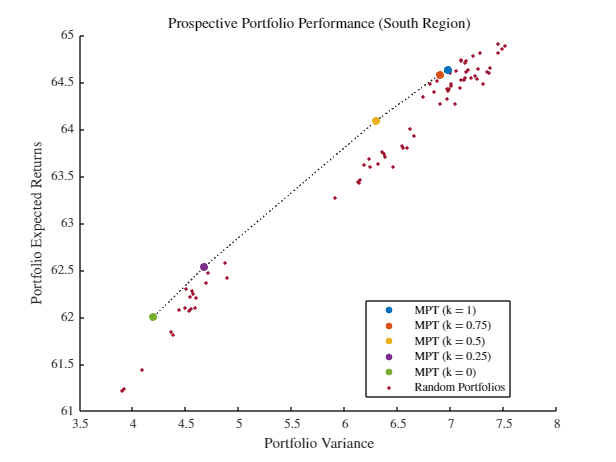


% plot the performance on future connectivity matrices
figure
visualiseMPT(portPerfMPT{3, 1}, portPerfMPT{3, 2}, names, portPerfRand{3, 1}, ...
    portPerfRand{3, 2}, "rand")
title("Prospective Portfolio Performance (South Region)")
saveFig("Prospective Portfolio Performance (South Region)")

% I wonder if the methods are just choosing the same reefs every single
% time - this is why I need to do the heatmap here

% will need to do a heatmap for each of the portfolio types, apart from the
% zero portfolio - will still do one for the random, given that will help
% me visually check
selCountsCTSouth = zeros(size(portPerfCTSouth, 2) - 1, nReefsCTSouth);

% loop over each of the repetitions
for r = 1:size(portPerfCTSouth, 1)

    % loop over each of the models
    for m = 1:(size(portPerfCTSouth, 2) - 1)
        selCountsCTSouth(m, :) = selCountsCTSouth(m, :) ...
            + mpaSelCTSouth{r}{m};
    end

end

% divide by the number of repetitions so that it becomes a proportion
selCountsCTSouth = selCountsCTSouth / size(portPerfCTSouth, 1);

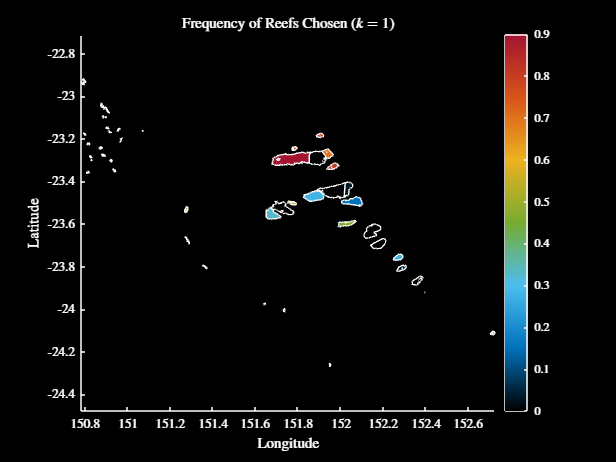

% test plotting one of the heatmaps here, for now just randomising things
% so that it works
modCurr = 1;
figure  
plotShapeStruct(GBRShapeCTSouth, [], selCountsCTSouth(modCurr, :), "fill")
xlabel("Longitude")
ylabel("Latitude")
title("Frequency of Reefs Chosen ($k = 1$) (South Region)")
darkFig()

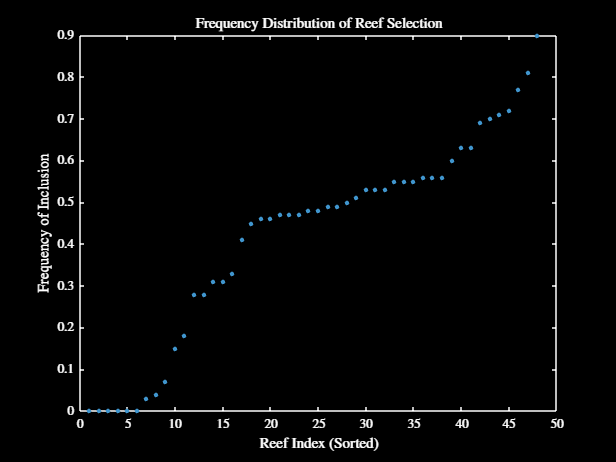


% let's just plot this as a regular plot as well
figure
plot(sort(selCountsCTSouth(modCurr, :)), '.', 'MarkerSize', 10)
xlabel("Reef Index (Sorted)")
ylabel("Frequency of Inclusion")
title("Frequency Distribution of Reef Selection (South Region)")
darkFig()

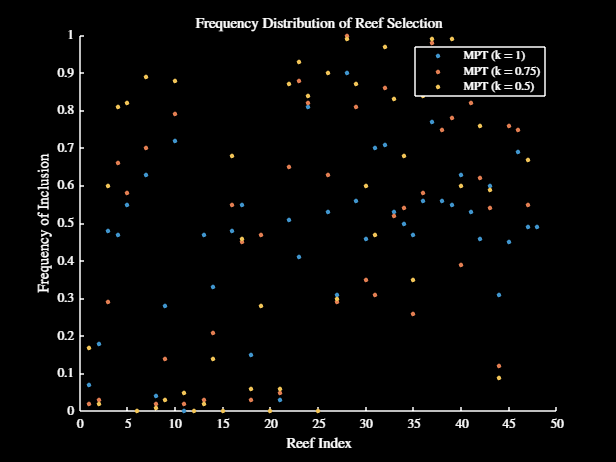

% recreate that above plot, but without any of the sortings to see if
% choices varied above 
figure
hold on
for m = 1:(size(selCountsCTSouth, 1) - 3)
    plot(selCountsCTSouth(m, :), '.', 'MarkerSize', 10, 'Color', ...
        getColour(m))
end
xlabel("Reef Index")
ylabel("Frequency of Inclusion")
title("Frequency Distribution of Reef Selection (South Region)")
legend(names(1:3))
darkFig()


% based on the fact that there the above dots aren't all just directly on
% top of each other is good, and indicates that different portfolios aren't
% just being selected each time

% should also go and make a plot of reef area vs selection probability just
% in case